# QLSC Assignment

## Niklas Brake

% Load Data
fid = fopen('datastd.csv');
txt = textscan(fid,'%s');
T = cellfun(@(X) strsplit(X,','),txt{1},'UniformOutput',false);
T = vertcat(T{:});
X = cellfun(@str2num,T(2:end,2:end),'un',0);
X = cell2mat(X);

fid = fopen('header.csv');
txt = textscan(fid,'%s');
Populations = string(strsplit(txt{1}{2},','));

fid = fopen('superpops.csv');
txt = textscan(fid,'%s');
T = cellfun(@(X) strsplit(X,','),txt{1},'UniformOutput',false);
T = vertcat(T{:});
SuperPopulations = string(cellfun(@str2num,T(:,2),'un',0));

fid = fopen('Ynew.csv');
txt = textscan(fid,'%s');
T = cellfun(@(X) strsplit(X,','),txt{1},'UniformOutput',false);
T = vertcat(T{:});
Y = cell2mat(cellfun(@str2num,T(2:end,2),'un',0));
SampleLabels = string(cellfun(@str2num,T(2:end,1),'un',0));

% Find PCAs
[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(X);

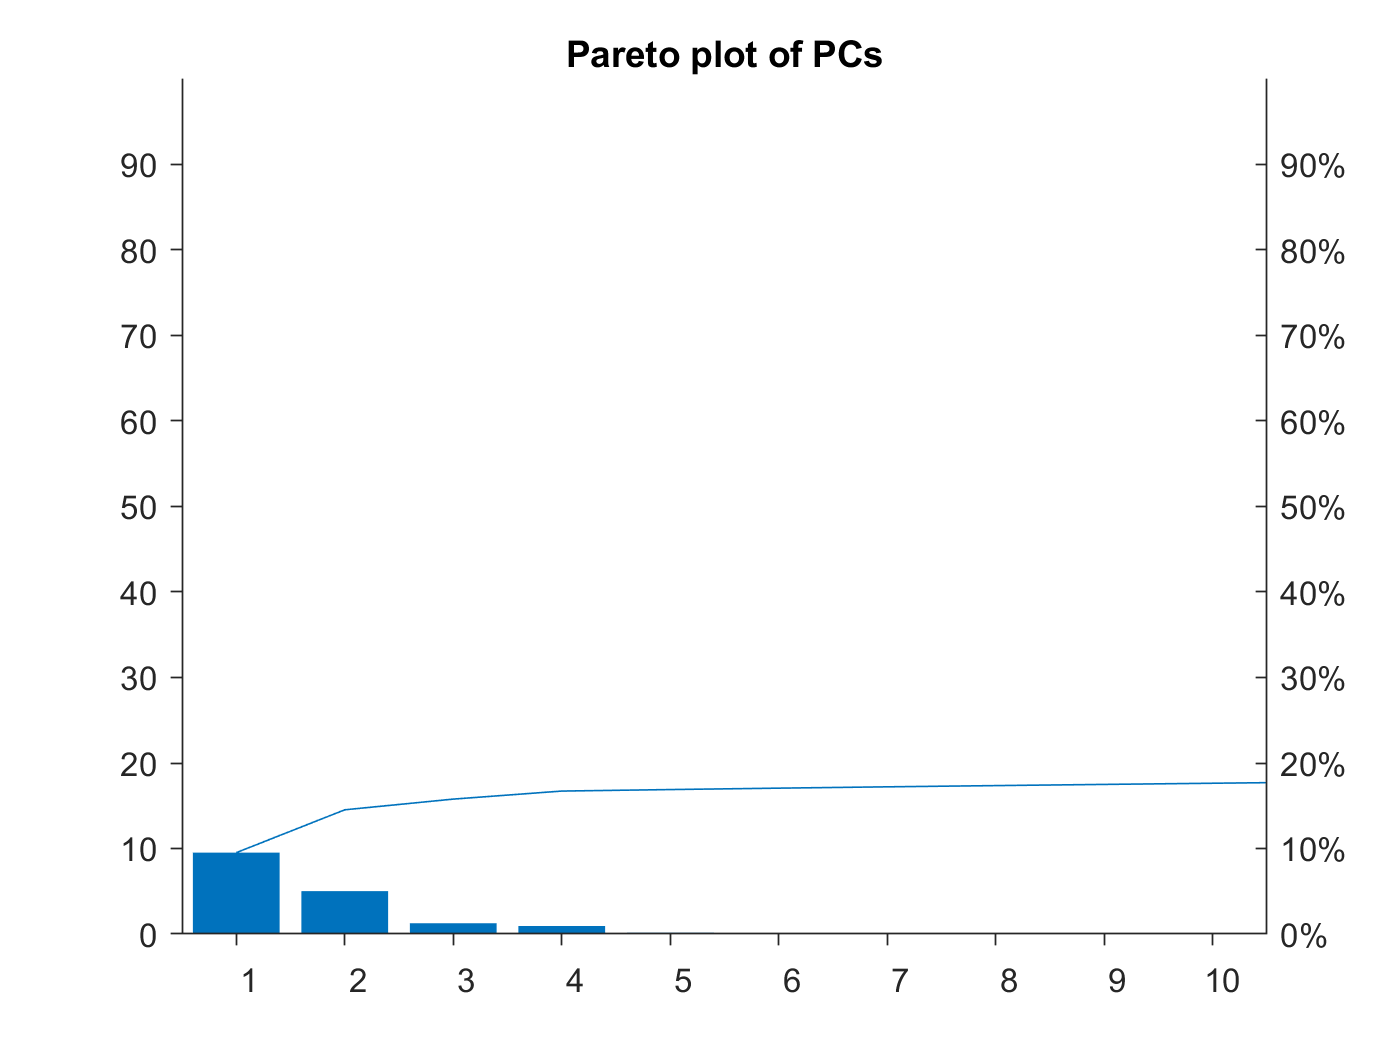

pareto(EXPLAINED); box off; set(gca,'TickDir','out'); title('Pareto plot of PCs');

Considering the variance explained by each of the PCAs, the first 6 were selected for the rest of the analysis.

SCORE = SCORE(:,1:6);
% Find residuals from phenotype to linear model based on first 6 PCAs
[~,~,stats] = glmfit(SCORE,Y);
Yresid = stats.resid;
% Find residuals from SNPs to linear model based on first 6 PCAs
Xresid = zeros(size(X));
for j = 1:size(X,2)
	[~,~,stats] = glmfit(SCORE,X(:,j));
	Xresid(:,j) = stats.resid;
end

% Select first super population for analysis
temp = unique(SuperPopulations);
selectedSuperPopulation = temp{1};
selectIdcs = find(strcmp(SuperPopulations,selectedSuperPopulation));
% Identify population belonging to selected super population
selectPops = unique(Populations(selectIdcs));
uniquePops = unique(Populations);

% For each population in our super population...
for k = 1:length(selectPops)
    % Find all individuals belonging to population k
    looIdcs = find(strcmp(selectPops{k},Populations));
    looIdcs = intersect(looIdcs,selectIdcs);
    % Find all individuals not in population k, but still in superpop
    remainIdcs = setdiff(selectIdcs,looIdcs);
    % Compute linear model between SNP residuals and phenotype residuals
    % on all individuals in superpop but not in pop k
    for j = 1:size(X,2)
	[~,~,stats] = glmfit(Xresid(remainIdcs,j),Yresid(remainIdcs));
	B(j,k) = stats.beta(2);
	P(j,k) = stats.p(2);
    end
end

testTheseThresholds = [1,0.5,0.01,1e-5,1e-8,1e-12];
% For several P_thresholds...
for i = 1:length(testTheseThresholds)
    P_Threshold = testTheseThresholds(i);
    % For each leave-one-out condition...
    for k = 1:length(selectPops)
        % All SNP residuals who contribute to the linear model with confidence 
        % determined by P_Threshold
        selectedSNPIdcs = P(:,k) < P_Threshold;
        % Calcute risk score based on these significant SNP residuals
        S(:,k) = Xresid(:,selectedSNPIdcs)*B(selectedSNPIdcs,k);
        % Calculate how well this risk score matches phenotype residual
        % for each population
        for K = 1:length(uniquePops)
            idcs = find(strcmp(Populations,uniquePops{K}));
            MSE(K,k,i) = sum((Yresid(idcs)-S(idcs,k)).^2)/length(idcs);
        end
    end
end


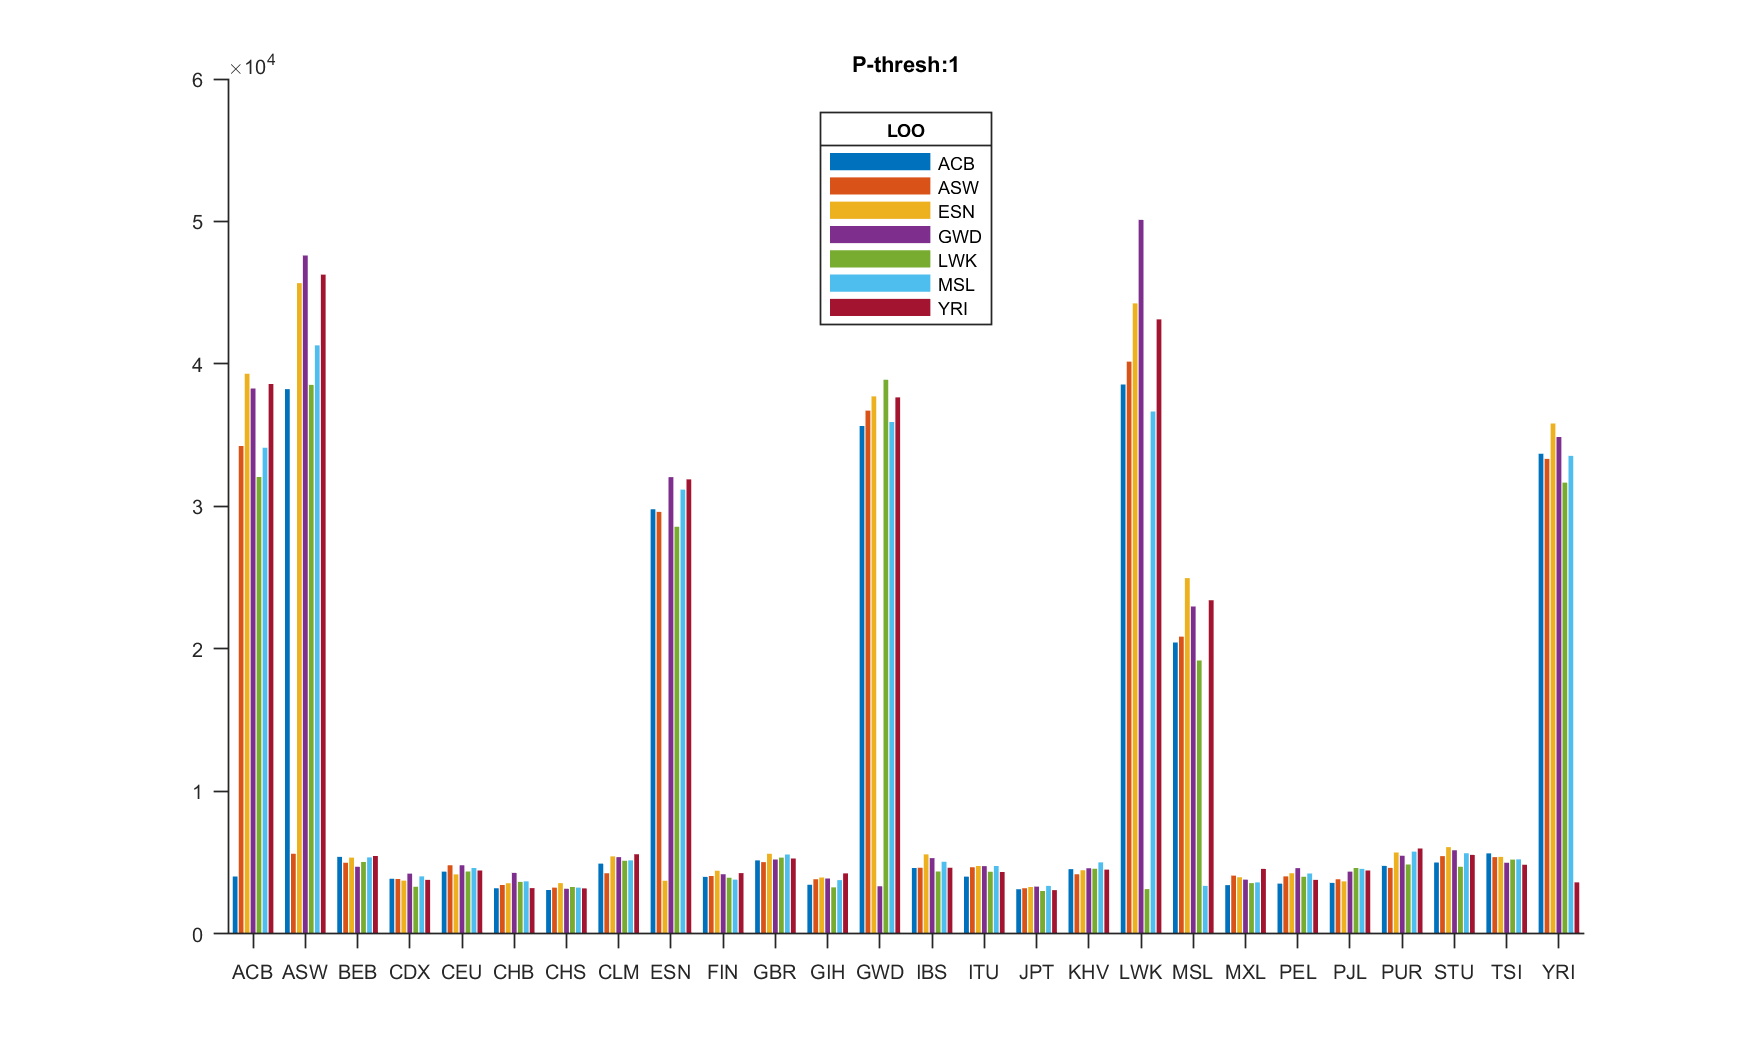

i = 1;
fig = figure(i);
bar(MSE(:,:,i));
title(['P-thresh:' num2str(testTheseThresholds(i))]);
set(gca,'XTick',[1:26]); set(gca,'XTickLabels',unique(Populations))
box off; set(gca,'TickDir','out')
L = legend(selectPops); L.Title.String = 'LOO'; L.Location = 'north';
pos = get(fig,'InnerPosition');
pos(3) = 700;
set(fig,'InnerPosition',pos);
set(gca,'FontSize',6);

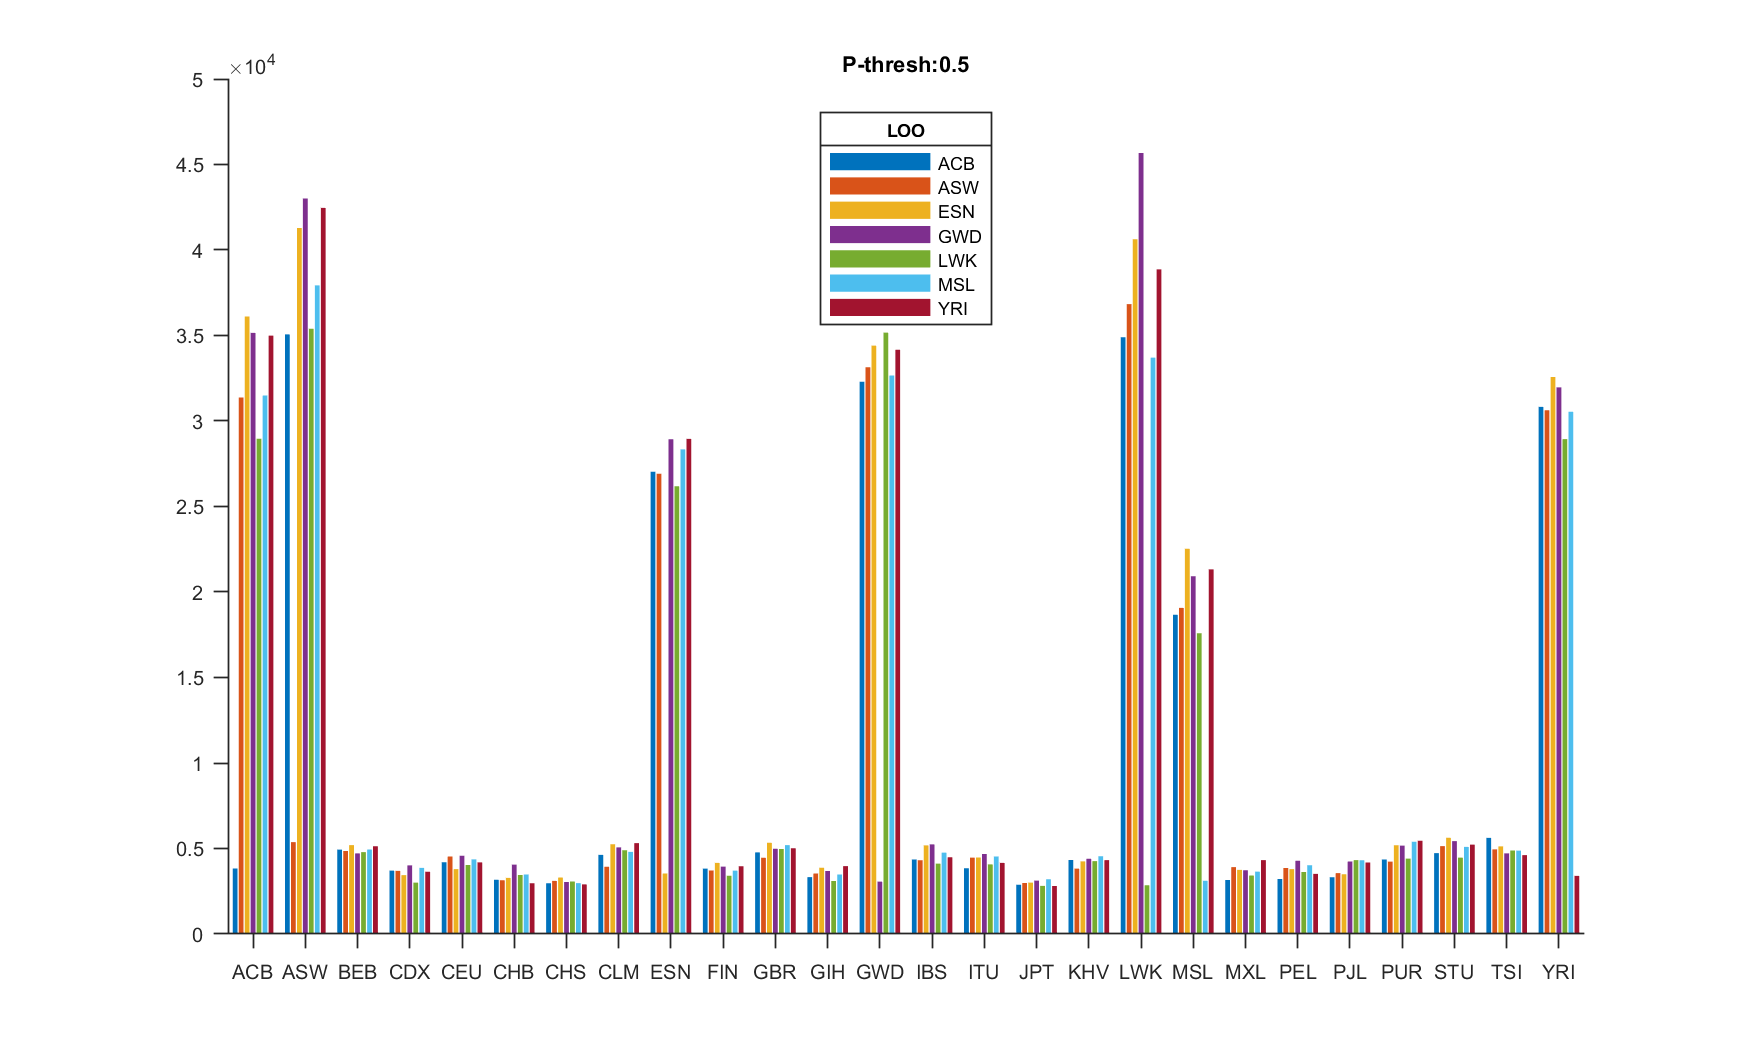

i = 2;
fig = figure(i);
bar(MSE(:,:,i));
title(['P-thresh:' num2str(testTheseThresholds(i))]);
set(gca,'XTick',[1:26]); set(gca,'XTickLabels',unique(Populations))
box off; set(gca,'TickDir','out')
L = legend(selectPops); L.Title.String = 'LOO'; L.Location = 'north';
pos = get(fig,'InnerPosition');
pos(3) = 700;
set(fig,'InnerPosition',pos);
set(gca,'FontSize',6);

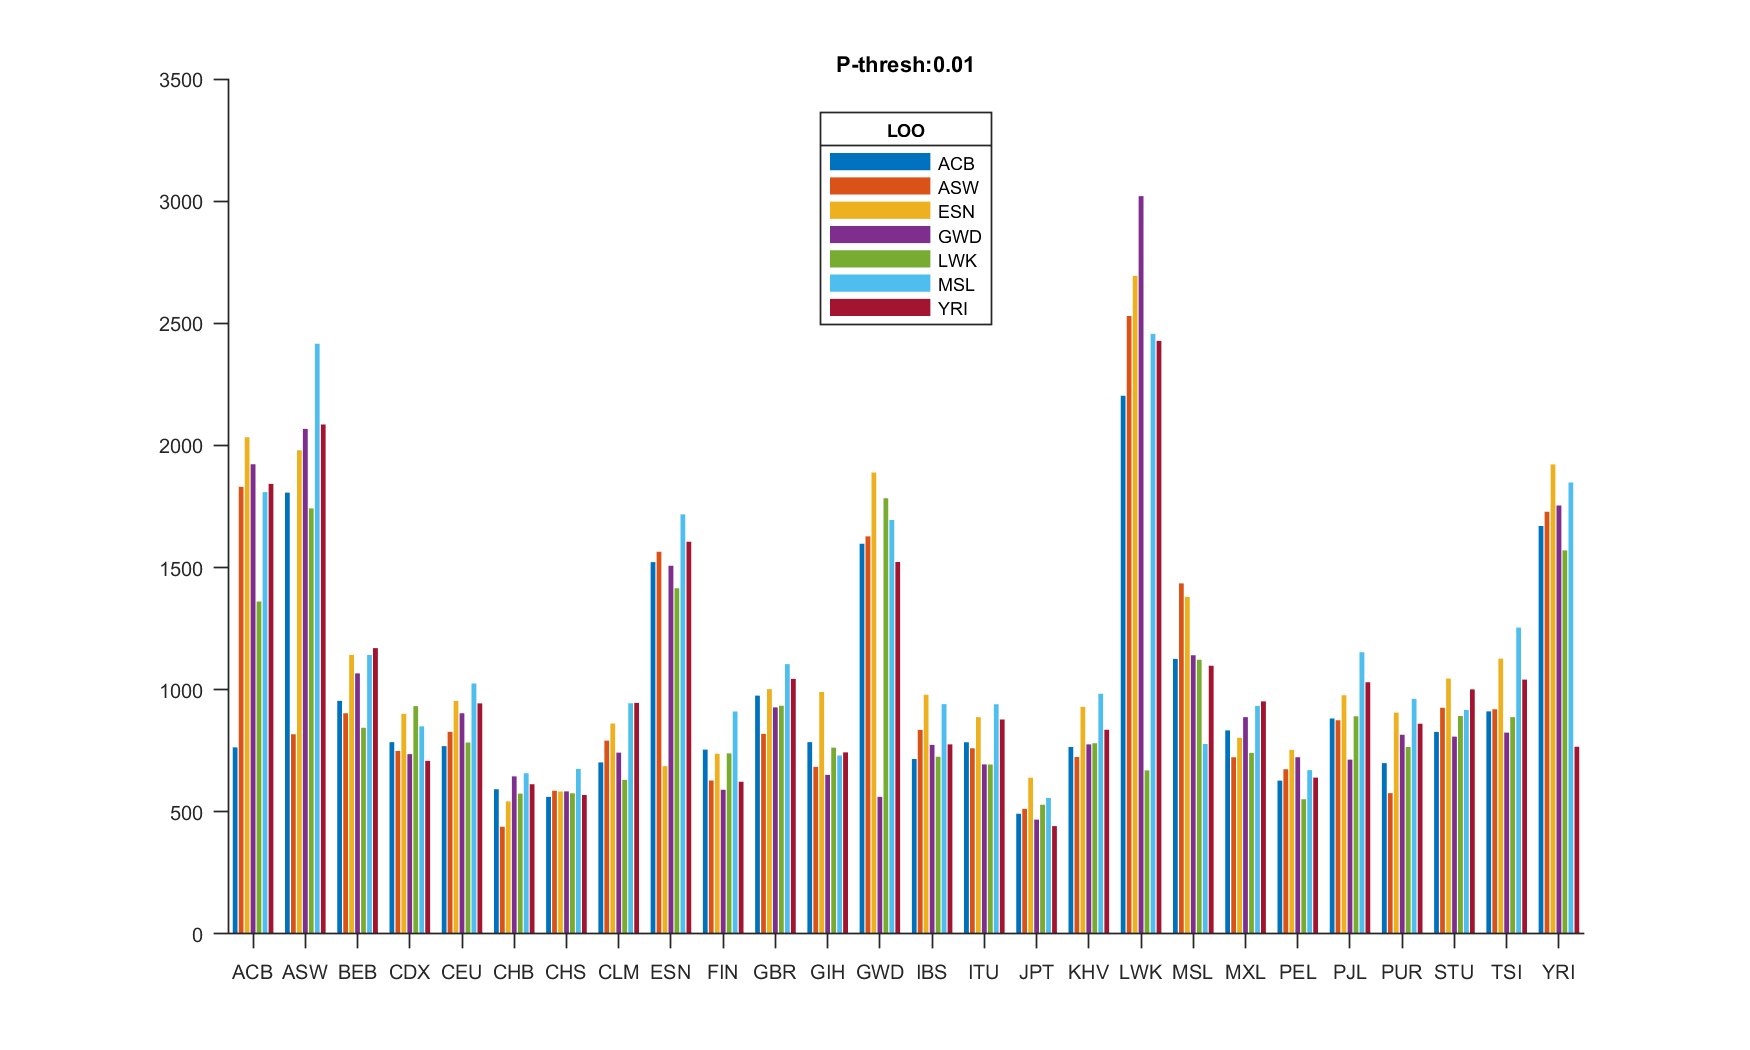

i = 3;
fig = figure(i);
bar(MSE(:,:,i));
title(['P-thresh:' num2str(testTheseThresholds(i))]);
set(gca,'XTick',[1:26]); set(gca,'XTickLabels',unique(Populations))
box off; set(gca,'TickDir','out')
L = legend(selectPops); L.Title.String = 'LOO'; L.Location = 'north';
pos = get(fig,'InnerPosition');
pos(3) = 700;
set(fig,'InnerPosition',pos);
set(gca,'FontSize',6);

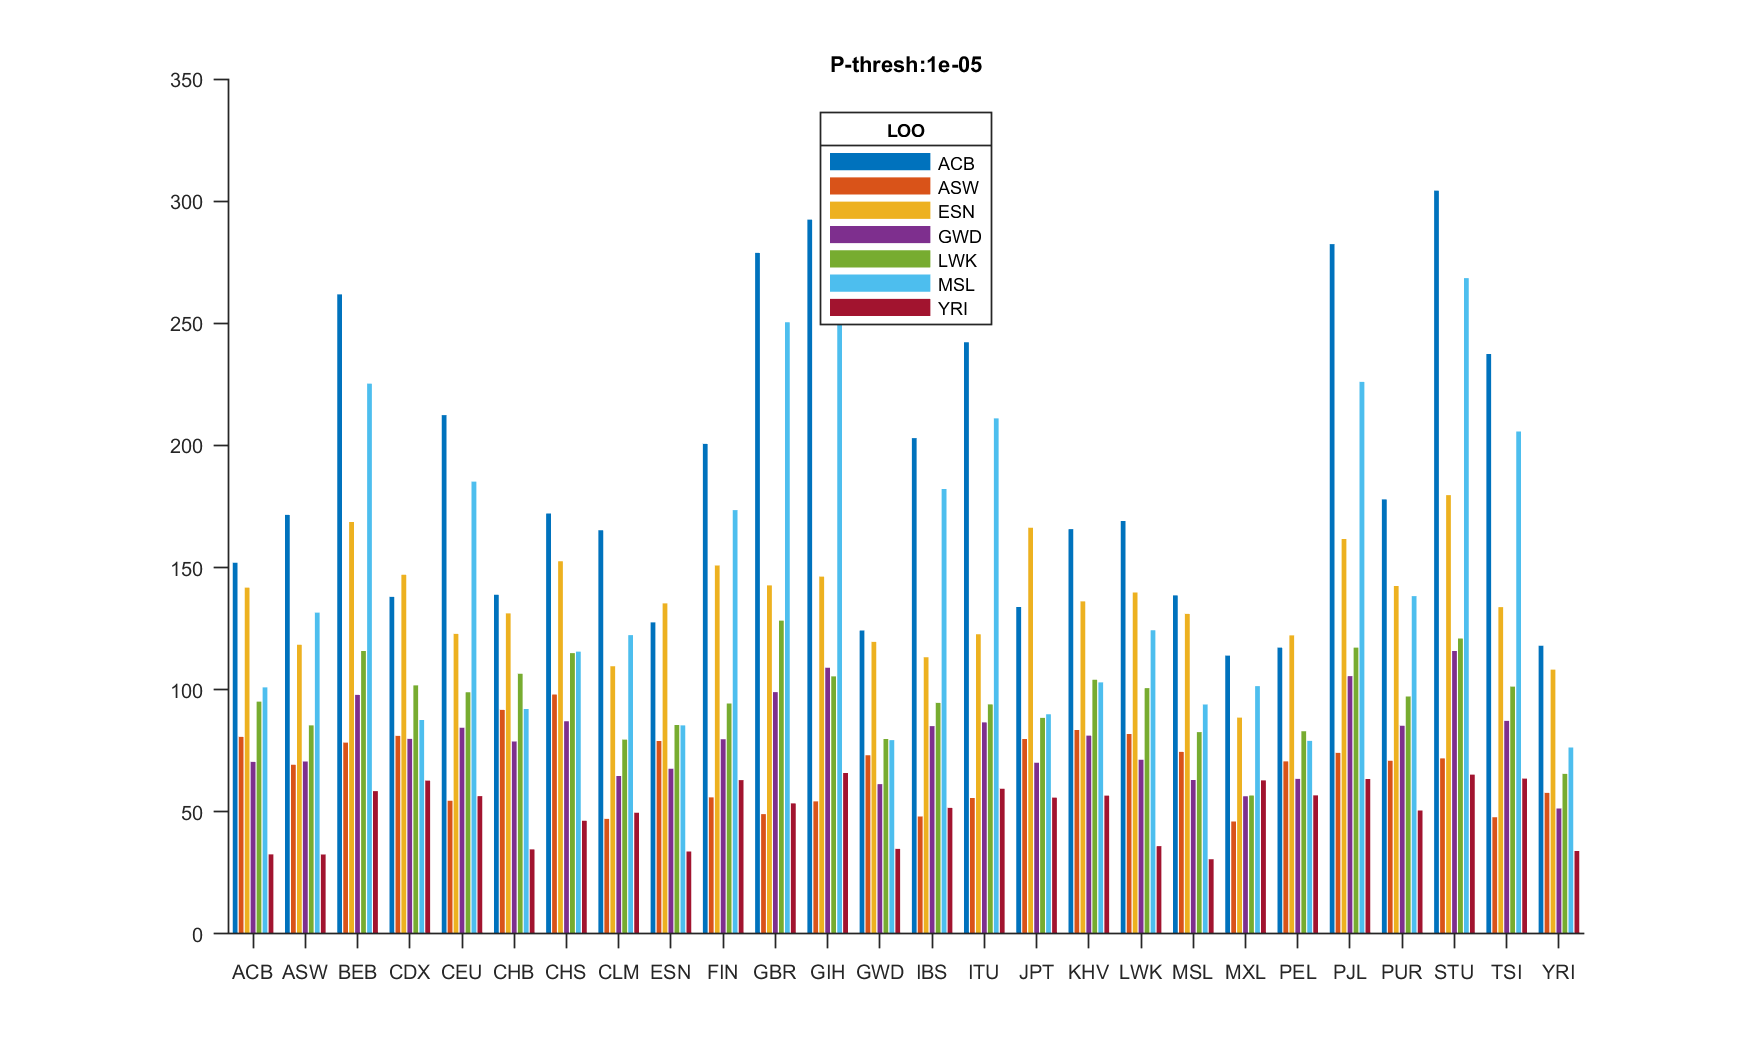

i = 4;
fig = figure(i);
bar(MSE(:,:,i));
title(['P-thresh:' num2str(testTheseThresholds(i))]);
set(gca,'XTick',[1:26]); set(gca,'XTickLabels',unique(Populations))
box off; set(gca,'TickDir','out')
L = legend(selectPops); L.Title.String = 'LOO'; L.Location = 'north';
pos = get(fig,'InnerPosition');
pos(3) = 700;
set(fig,'InnerPosition',pos);
set(gca,'FontSize',6);
pos = get(fig,'InnerPosition');
pos(3) = 700;
set(fig,'InnerPosition',pos);
set(gca,'FontSize',6);

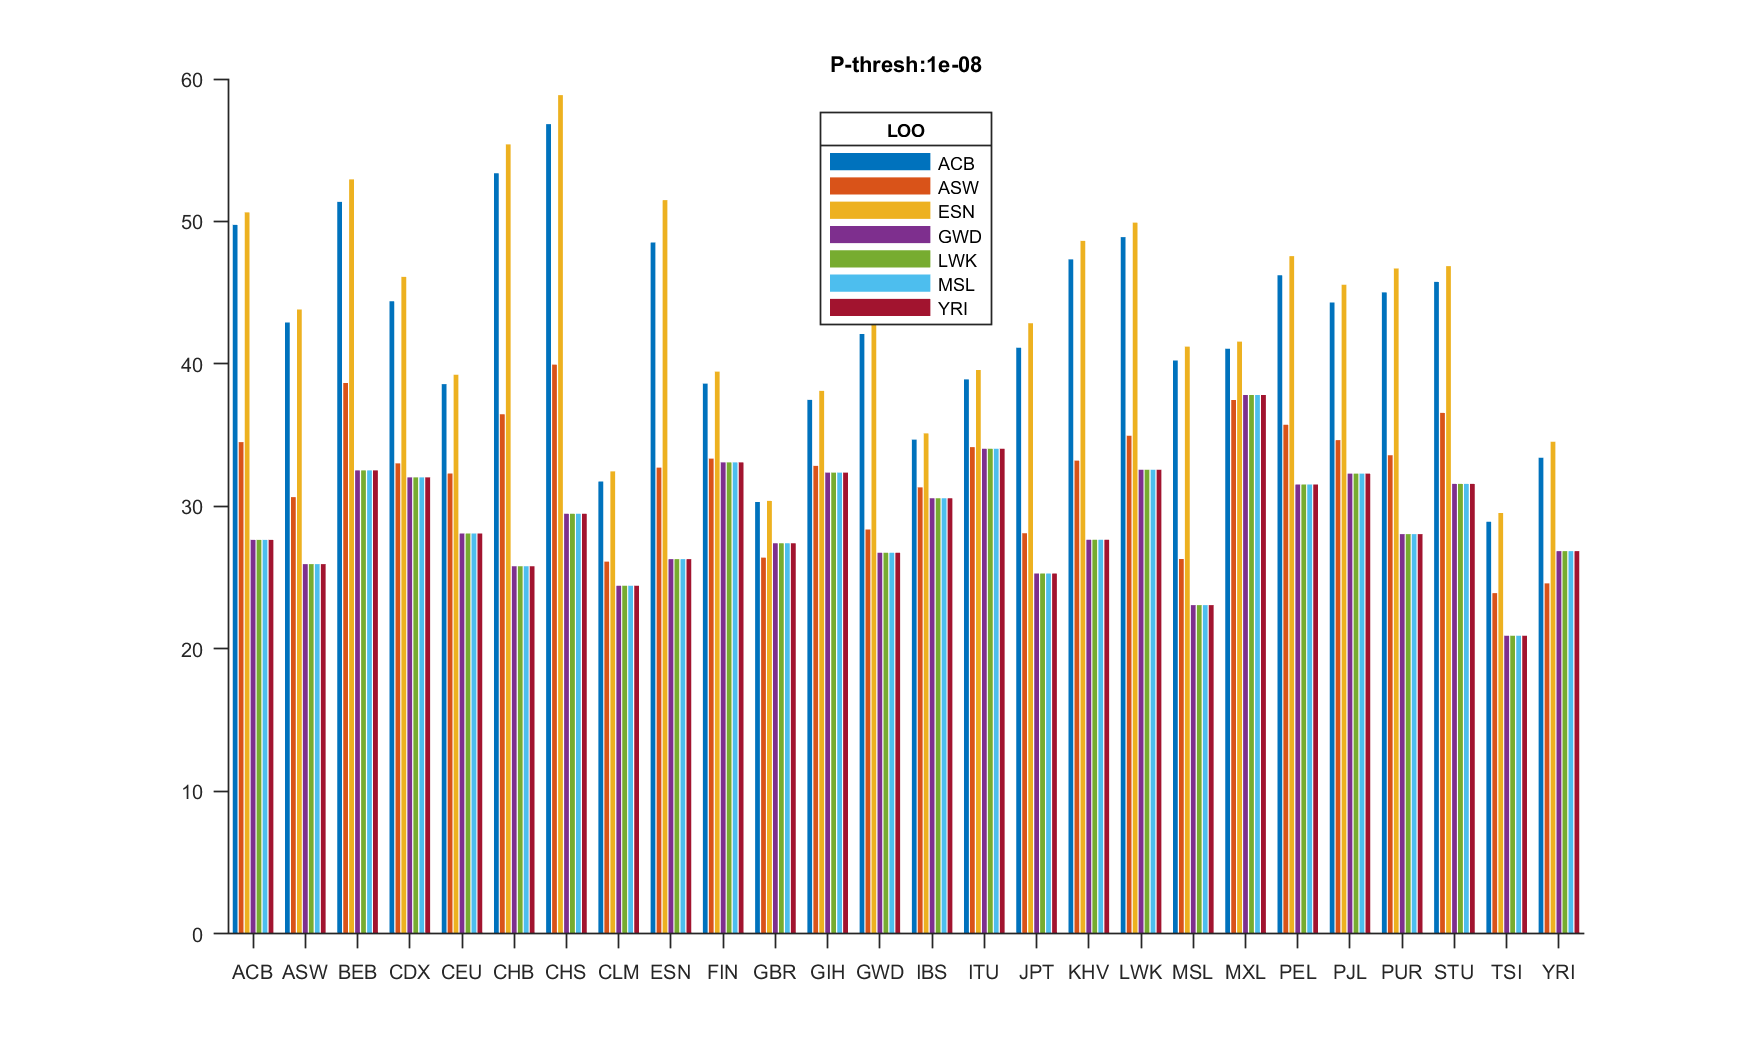

i = 5;
fig = figure(i);
bar(MSE(:,:,i));
title(['P-thresh:' num2str(testTheseThresholds(i))]);
set(gca,'XTick',[1:26]); set(gca,'XTickLabels',unique(Populations))
box off; set(gca,'TickDir','out')
L = legend(selectPops); L.Title.String = 'LOO'; L.Location = 'north';
pos = get(fig,'InnerPosition');
pos(3) = 700;
set(fig,'InnerPosition',pos);
set(gca,'FontSize',6);

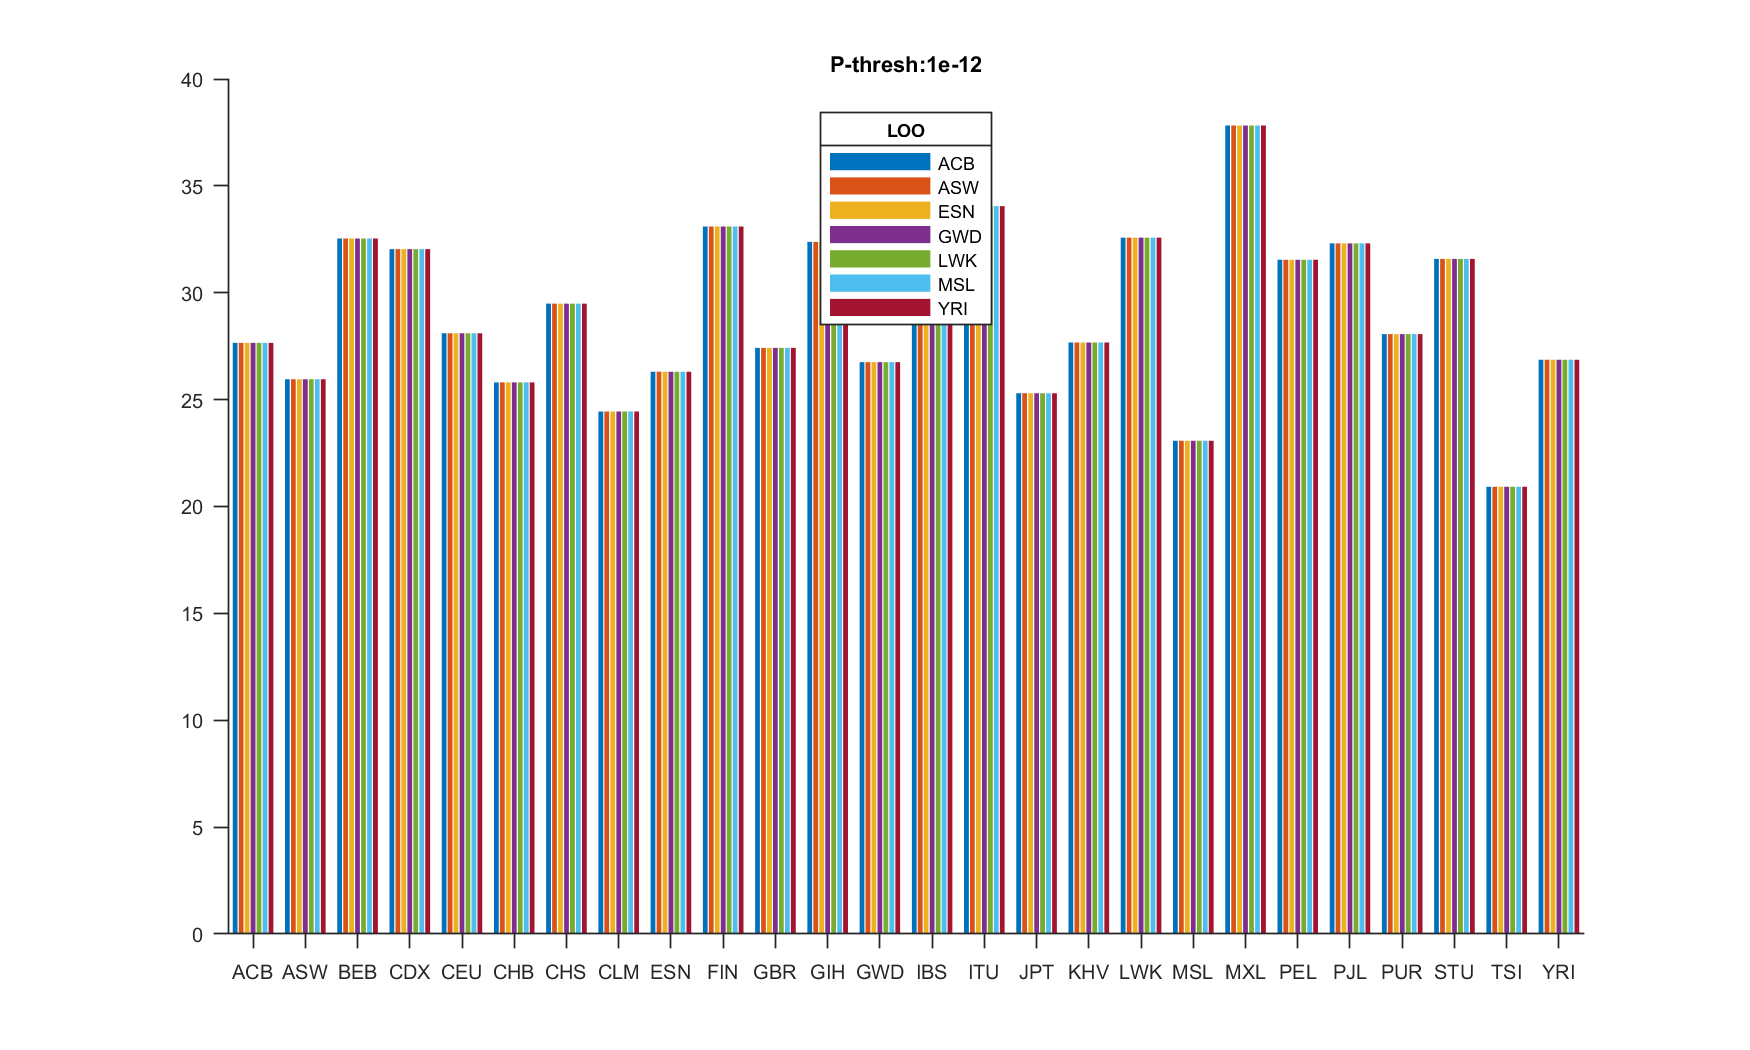

i = 6;
fig = figure(i);
bar(MSE(:,:,i));
title(['P-thresh:' num2str(testTheseThresholds(i))]);
set(gca,'XTick',[1:26]); set(gca,'XTickLabels',unique(Populations))
box off; set(gca,'TickDir','out')
L = legend(selectPops); L.Title.String = 'LOO'; L.Location = 'north';

The data shows that when we have a very lax p-value threshold, our model is very biased, and gives very different results for the data it was trained on in comparison to the data we set aside. Interestingly, the bias has the same impact on populations outside of our superpopulation as on our leave-one-out population. This is because the PCA correction removed any inter-superpopulation correlation. As we decrease our p-value threshold, this biase to the training data decreases until, at around a threshold of 1e-5, the bias is no longer appreciable.  For very low p-values thresholds, we are so selective that there is no bias at all, and so all leave-one-out conditions are equivalent. The leave-one-out cross validation allows us to predict the generalization error our model with have on populations out side of our super population.